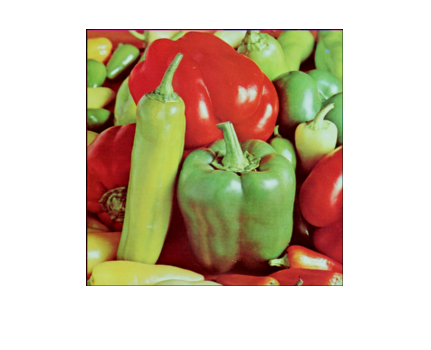

filter = zeros(3,3);
filter(1:end,1:end) = 1/9;

A = imread('input.png');
[x,y,z] = size(A);

rows = 2;
cols = 2;

if z==1
    b = conv2(filter, A);
    c = decimation(b,rows,cols);
    f = c;
else
    b = conv2(filter, A(:,:,1));
    c = conv2(filter, A(:,:,2));
    d = conv2(filter, A(:,:,3));
    [p,q,r] = size(b);
    e = zeros(p,q,3);
    e(1:end,1:end,1) = b(1:end,1:end);
    e(1:end,1:end,2) = c(1:end,1:end);
    e(1:end,1:end,3) = d(1:end,1:end); 
    f = decimation(e,rows,cols);
end

imshow(f);